
%%======================================================
%% STEP 1a: Generate data from two 2D distributions.

mu1 = [1 2];       % Mean
sigma1 = [ 3 .2;   % Covariance matrix
          .2  2];
m1 = 200;          % Number of data points.

mu2 = [-1 -2];
sigma2 = [2 0;
          0 1];
m2 = 100;

% Generate sample points with the specified means and covariance matrices.
R1 = chol(sigma1)

R1 =    1.732050807568877   0.115470053837925
                   0   1.409491634124398


X1 = randn(m1, 2) * R1

X1 =    1.166880371403286   1.969165898203045
  -1.158937703990178  -1.470452971457113
  -0.693379256922422   2.516149725756272
  -1.163595936591501  -0.605338326822336
   0.997018703032924  -1.979748486105753
  -1.347697501748727  -0.961873332067884
  -1.842142040355312   1.194361819079781
   0.957786513312211   1.552175887474491
  -0.733400260522639   0.176945655434243
   0.626287340881615   0.446840836419507
  -0.609490045687552   0.851442446317799
   0.466858200917431  -2.025383428249415
  -4.441756578239016  -1.116032096750721
   0.806900339256301  -2.525786802752826
   3.210461727324598  -0.418976252085622
   1.800101940380089   1.458001549237307
   1.577719156062820   1.116408941657700
  -0.415226768557357   3.196993495432921
   0.313497870272914   0.255901104686706
   0.423052624806390  -3.011352165266991
   0.166957373510912   2.392324682080831
  -1.438413631961953   1.711469743494959
  -0.610118682644225  -0.861888048872230
  -0.302719248385239   0.293591964862322
  -0.832516

X1 = X1 + repmat(mu1, size(X1, 1), 1) % 200 x 2

X1 =    2.166880371403286   3.969165898203045
  -0.158937703990178   0.529547028542887
   0.306620743077578   4.516149725756271
  -0.163595936591501   1.394661673177664
   1.997018703032925   0.020251513894247
  -0.347697501748727   1.038126667932116
  -0.842142040355312   3.194361819079781
   1.957786513312211   3.552175887474491
   0.266599739477361   2.176945655434243
   1.626287340881615   2.446840836419507
   0.390509954312448   2.851442446317799
   1.466858200917431  -0.025383428249415
  -3.441756578239016   0.883967903249279
   1.806900339256301  -0.525786802752826
   4.210461727324597   1.581023747914378
   2.800101940380089   3.458001549237307
   2.577719156062820   3.116408941657700
   0.584773231442643   5.196993495432920
   1.313497870272914   2.255901104686706
   1.423052624806390  -1.011352165266991
   1.166957373510912   4.392324682080831
  -0.438413631961953   3.711469743494959
   0.389881317355775   1.138111951127770
   0.697280751614761   2.293591964862322
   0.167483

% using repmat to add mu1 to all rows of X1

R2 = chol(sigma2)

R2 =    1.414213562373095                   0
                   0   1.000000000000000


X2 = randn(m2, 2) * R2

X2 =   -2.141717761157474  -1.684758848541009
   1.451250956510720   0.413148529949933
  -1.072154158508772   0.501745219289013
   2.939223388050839   0.083064345164233
  -3.142363592499755   0.157798051973368
   0.634647623889568  -0.527942514299507
   0.000885460900337   0.723060699828803
  -1.069483887349636  -0.849941652073993
   0.571801652723808  -0.796384050833210
  -1.122677502752363   0.725337571127987
   1.215917056106035   1.686544476981596
   0.094567344559785  -0.386394169497248
  -2.318443886150994  -0.505078413652473
  -3.429114212853964   0.408073894625228
  -0.401396131184781   1.072356141861394
   1.620414807853979   0.967982891147789
   0.256212066361307   0.270145532752676
   0.076721408969639  -0.634406535588807
   0.972630545447030   0.629763180328370
  -1.970575504376233  -0.079233753951589
   2.015771555457583   1.376949165612293
  -1.264096430186905  -1.408212489933244
   0.053407350854165   0.141231683307765
  -0.514164618219439   1.289719394940369
   0.211504

X2 = X2 + repmat(mu2, size(X2, 1), 1) % adding mu2 to all rows

X2 =   -3.141717761157474  -3.684758848541009
   0.451250956510720  -1.586851470050067
  -2.072154158508772  -1.498254780710987
   1.939223388050839  -1.916935654835767
  -4.142363592499755  -1.842201948026632
  -0.365352376110432  -2.527942514299507
  -0.999114539099663  -1.276939300171197
  -2.069483887349636  -2.849941652073993
  -0.428198347276192  -2.796384050833209
  -2.122677502752364  -1.274662428872013
   0.215917056106035  -0.313455523018404
  -0.905432655440215  -2.386394169497248
  -3.318443886150994  -2.505078413652472
  -4.429114212853964  -1.591926105374772
  -1.401396131184781  -0.927643858138606
   0.620414807853979  -1.032017108852211
  -0.743787933638693  -1.729854467247324
  -0.923278591030361  -2.634406535588807
  -0.027369454552970  -1.370236819671630
  -2.970575504376233  -2.079233753951589
   1.015771555457583  -0.623050834387707
  -2.264096430186905  -3.408212489933244
  -0.946592649145835  -1.858768316692235
  -1.514164618219439  -0.710280605059631
  -0.788495


X = [X1; X2];

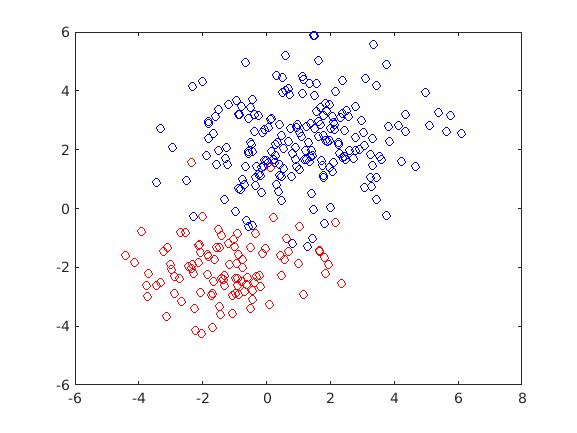


%%=====================================================
%% STEP 1b: Plot the data points and their pdfs.

figure(1);

% Display a scatter plot of the two distributions.
hold off;

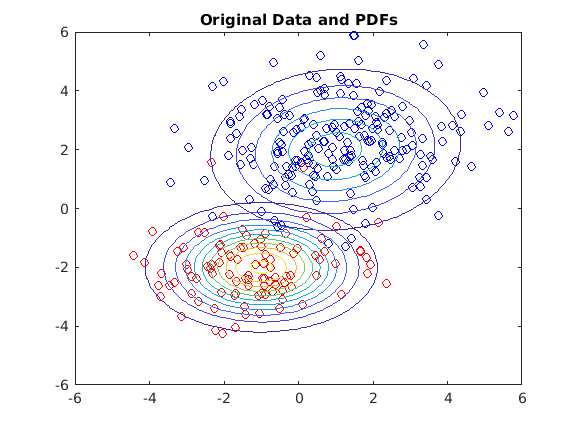

plot(X1(:, 1), X1(:, 2), 'bo');
hold on;
plot(X2(:, 1), X2(:, 2), 'ro');

set(gcf,'color','white') % White background for the figure.

% First, create a [10,000 x 2] matrix 'gridX' of coordinates representing
% the input values over the grid.
gridSize = 100;
u = linspace(-6, 6, gridSize);
[A B] = meshgrid(u, u);
gridX = [A(:), B(:)];

% Calculate the Gaussian response for every value in the grid.
z1 = gaussianND(gridX, mu1, sigma1);
z2 = gaussianND(gridX, mu2, sigma2);

% Reshape the responses back into a 2D grid to be plotted with contour.
Z1 = reshape(z1, gridSize, gridSize);
Z2 = reshape(z2, gridSize, gridSize);

% Plot the contour lines to show the pdf over the data.
[C, h] = contour(u, u, Z1);
[C, h] = contour(u, u, Z2);

axis([-6 6 -6 6])
title('Original Data and PDFs');


%set(h,'ShowText','on','TextStep',get(h,'LevelStep')*2);


%% STEP 4: Plot the data points and their estimated pdfs.

% Display a scatter plot of the two distributions.
figure(2);
hold off;
plot(X1(:, 1), X1(:, 2), 'bo');
hold on;
plot(X2(:, 1), X2(:, 2), 'ro');

set(gcf,'color','white') % White background for the figure.

plot(mu1(1), mu1(2), 'kx');
plot(mu2(1), mu2(2), 'kx');

% First, create a [10,000 x 2] matrix 'gridX' of coordinates representing
% the input values over the grid.
gridSize = 100;
u = linspace(-6, 6, gridSize);
[A B] = meshgrid(u, u);
gridX = [A(:), B(:)];

% Calculate the Gaussian response for every value in the grid.
z1 = gaussianND(gridX, mu(1, :), sigma{1});
z2 = gaussianND(gridX, mu(2, :), sigma{2});

% Reshape the responses back into a 2D grid to be plotted with contour.
Z1 = reshape(z1, gridSize, gridSize);
Z2 = reshape(z2, gridSize, gridSize);

% Plot the contour lines to show the pdf over the data.
[C, h] = contour(u, u, Z1);
[C, h] = contour(u, u, Z2);
axis([-6 6 -6 6])

title('Original Data and Estimated PDFs');
